# **Progetto MPSMF**

warning('off','all');
Titolo = importATVIfile('AAPL.csv');
VolumeTotale= sum(Titolo.Volume);
PercentualeVolume =Titolo.Volume/ VolumeTotale;

Si calcolano i rendimenti logaritmici giornalieri

Titolo = addvars(Titolo,PercentualeVolume);
LogClose = log(Titolo.AdjClose);
LogRet = diff(LogClose);
Titolo = Titolo(1:height(Titolo)-1,:);
Datenum = datenum(Titolo.Date);
Titolo = addvars(Titolo,LogRet);
Titolo = addvars(Titolo,Datenum);
Titolo

Titolo = 251×7 table
       Date       Close     AdjClose      Volume      PercentualeVolume      LogRet       Datenum  
    __________    ______    ________    __________    _________________    __________    __________

    2018-07-16    190.91     188.05     1.5043e+07        0.0018396         0.0028247    7.3726e+05
    2018-07-17    191.45     188.58     1.5535e+07        0.0018997        -0.0054996    7.3726e+05
    2018-07-18     190.4     187.55     1.6393e+07        0.0020048         0.0077431    7.3726e+05
    2018-07-19    191.88        189     2.0287e+07        0.0024809        -0.0022958    7.3726e+05
    2018-07-20    191.44     188.57     2.0676e+07        0.0025285        0.00088753    7.3726e+05
    2018-07-23    191.61     188.74     

Plot e scatter plot delle serie

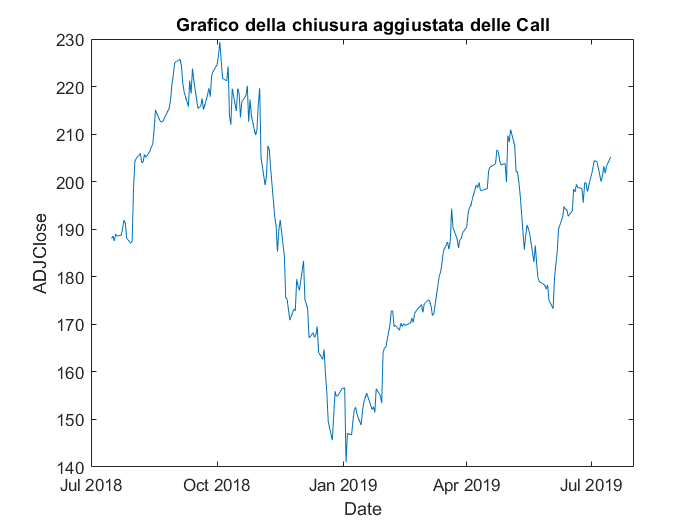

plot(Titolo.Date,Titolo.AdjClose);
title("Grafico della chiusura aggiustata delle Call");
xlabel("Date");
ylabel("ADJClose");

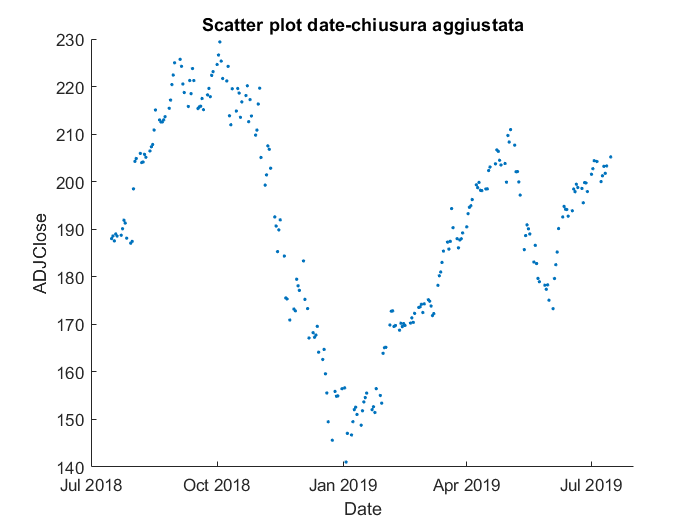


scatter(Titolo.Date,Titolo.AdjClose,'.');
title("Scatter plot date-chiusura aggiustata");
xlabel("Date");
ylabel("ADJClose");

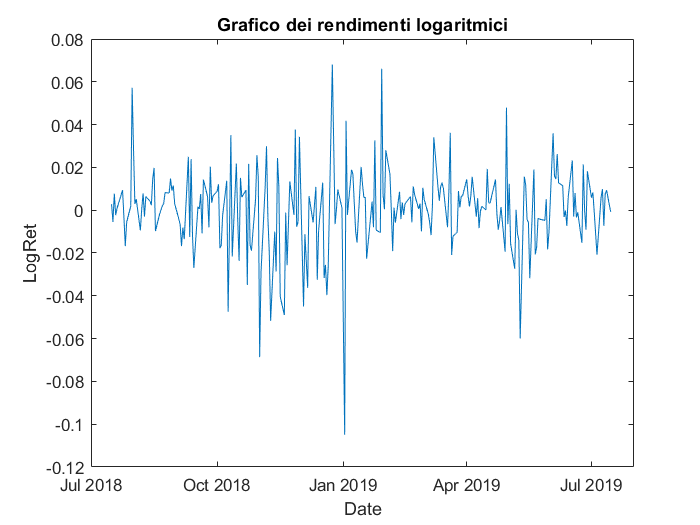


plot(Titolo.Date,LogRet);
title("Grafico dei rendimenti logaritmici");
xlabel("Date");
ylabel("LogRet");

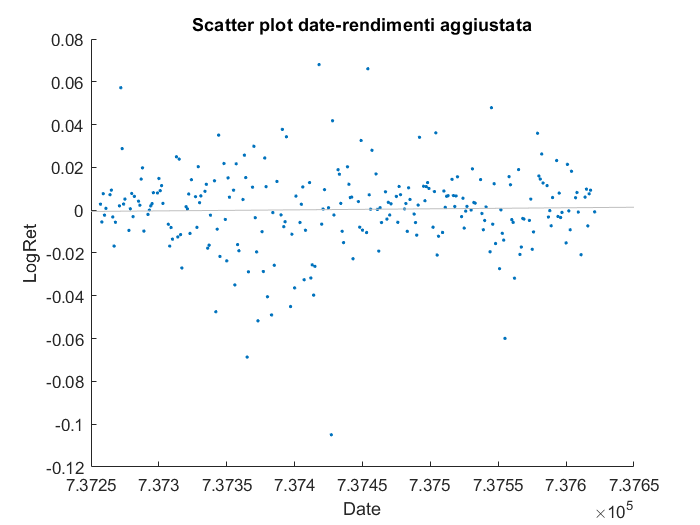


scatter(Titolo.Datenum,LogRet,'.');
title("Scatter plot date-rendimenti aggiustata");
xlabel("Date");
ylabel("LogRet");
hold on;
lsline;
hold off;

Test per la stazionarietà

TestSTazionarieta(LogRet);

KPSS Test
   0

ADF Test - Trend-stationary model
   1   1   1   1   1   1   1   1

ADF Test - Autoregressive model
   1   1   1   1   1   1   1   1

ADF Test - Autoregressive model with drift variant
   1   1   1   1   1   1   1   1



Correlazione

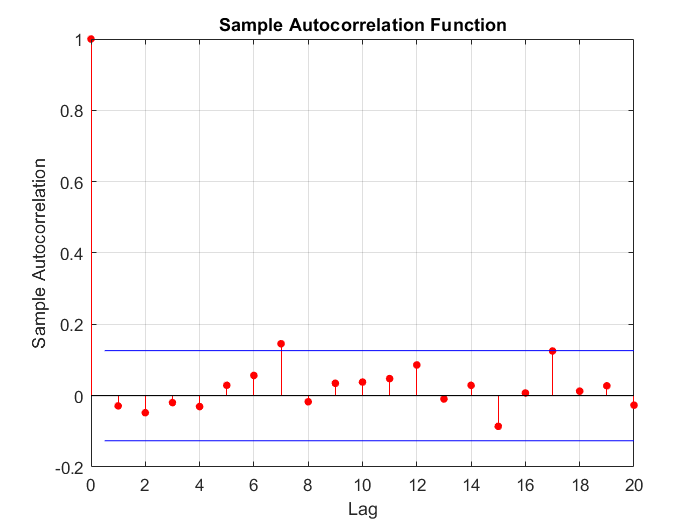

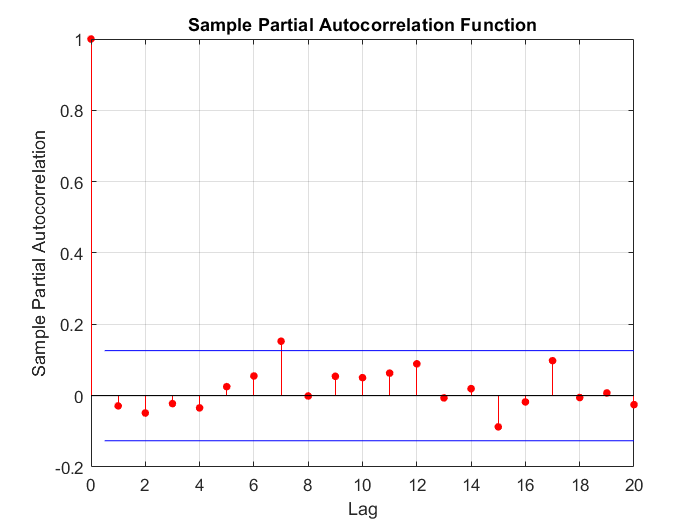

Ljung-Box Q-test for residual autocorrelation
   0   0   0   0   0   0   0



TestCorrelazione(LogRet);

Test di Normalità

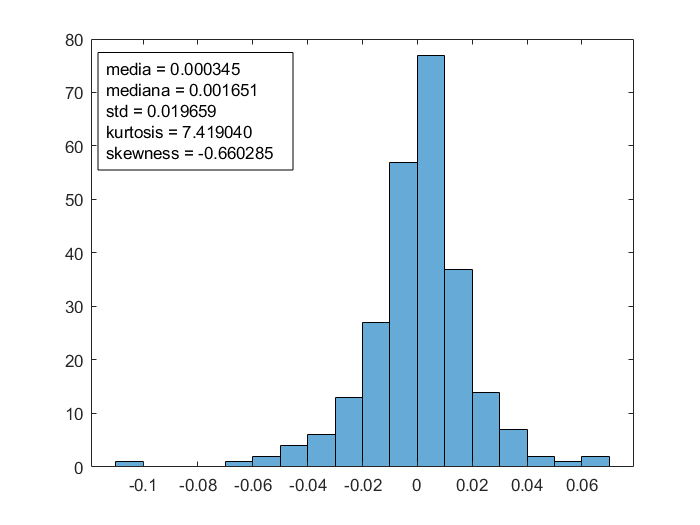

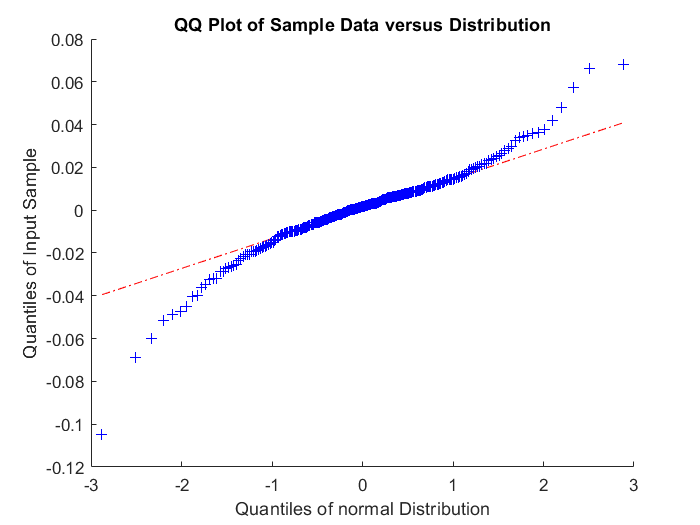

Lilliefors Test
     1

Jarque-Bera Test
     1



TestNormalita(LogRet);

Test Eteroschedasticità

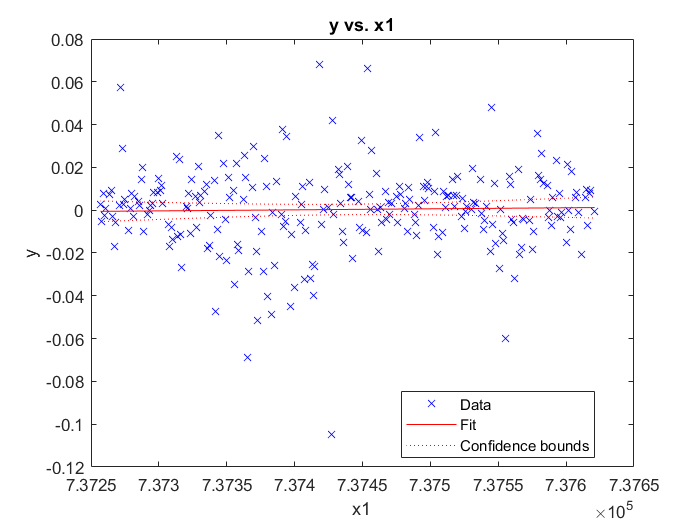

TestEteroschedasticita(Titolo);

Poichè non si hanno evidenze di normalità, si cerca di ridurre la grandezza del dataset e trovare un periodo abbastanza lungo in cui si possa affermare la normalità delle differenze logaritmiche.

A questo scopo si cerca di determinare un periodo in cui si possa considerare la distribuzione dei rendimenti logaritmici normale.

# **RIDUZIONE DELLA SERIE **

Titolo_Ristretto= Titolo(height(Titolo)-20:height(Titolo),:)

Titolo_Ristretto = 21×7 table
       Date       Close     AdjClose      Volume      PercentualeVolume      LogRet        Datenum  
    __________    ______    ________    __________    _________________    ___________    __________

    2019-06-14    192.74     192.74     1.8762e+07        0.0022943          0.0059488    7.3759e+05
    2019-06-17    193.89     193.89     1.4669e+07        0.0017939           0.023246    7.3759e+05
    2019-06-18    198.45     198.45     2.6551e+07        0.0032469         -0.0029269    7.3759e+05
    2019-06-19    197.87     197.87     2.1124e+07        0.0025833          0.0080035     7.376e+05
    2019-06-20    199.46     199.46     2.1514e+07         0.002631         -0.0034151     7.376e+05
    2019-06-21    198.78


TestSTazionarieta(Titolo_Ristretto.LogRet);

KPSS Test
   0

ADF Test - Trend-stationary model
   1   1   0   0

ADF Test - Autoregressive model
   1   1   1   1

ADF Test - Autoregressive model with drift variant
   1   1   0   1



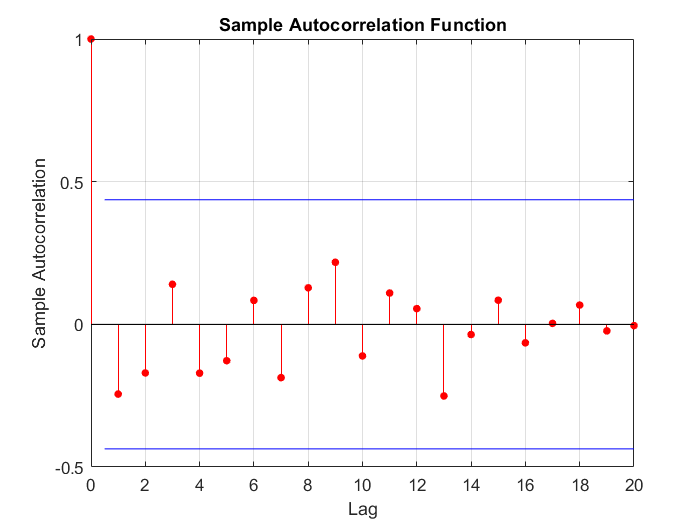

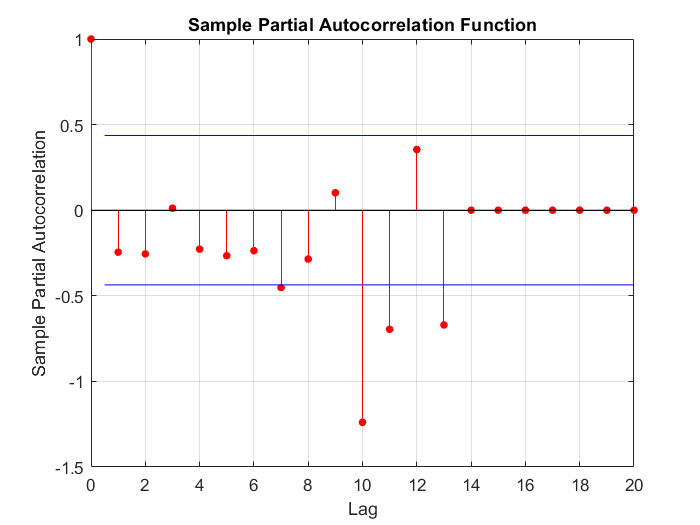

Ljung-Box Q-test for residual autocorrelation
   0   0   0



TestCorrelazione(Titolo_Ristretto.LogRet);

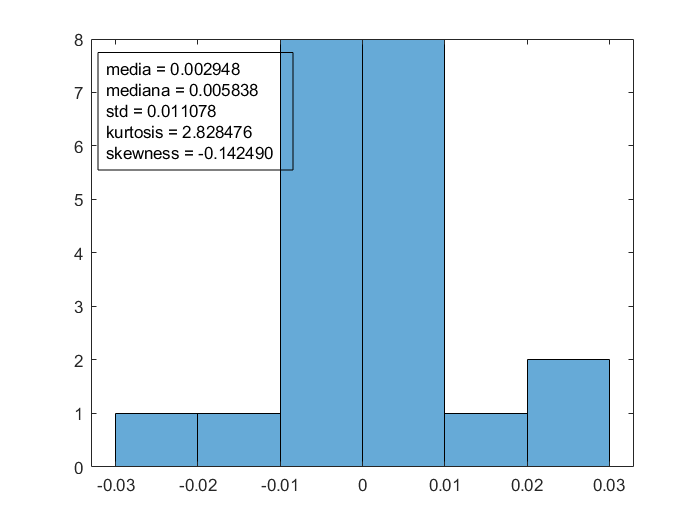

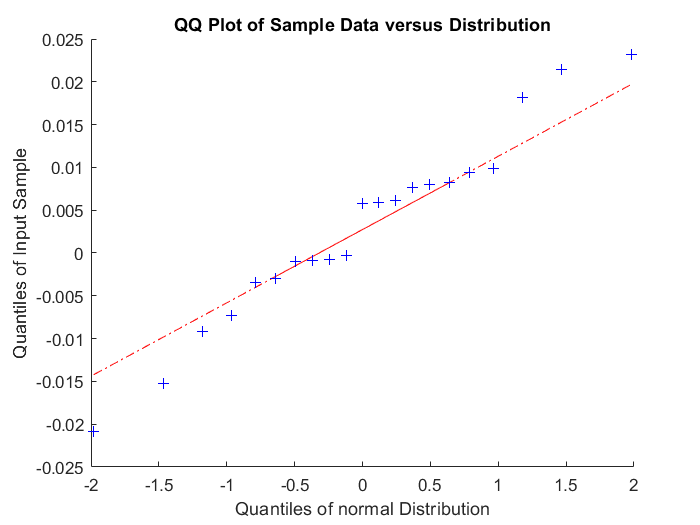

Lilliefors Test
     0

Jarque-Bera Test
     0



TestNormalita(Titolo_Ristretto.LogRet);

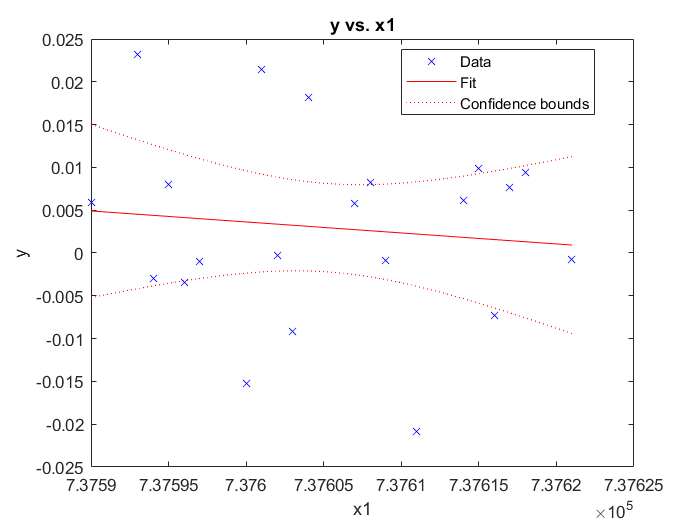

TestEteroschedasticita(Titolo_Ristretto);

Dopo aver preso in considerazione un set ristetto di dati, è possibile approssimare la distribuione dei rendimenti giornalieri come lognormale.

Si procese quindi al calcolo della volatilità del titolo ed all'applicazione dei modelli visti a lezione per stimare i valori di un opzione Call europea.

Si considera un insieme di opzioni Call ( prese da yahoo finance) del titolo in questione, prese in data 15/07/19 e maturità in data 30/08/19

%S0=204.67;

S0=203.35;
file=importfile("aapCallPut.CSV");
Calls=file(contains(file.Type,"Call"),:);
Puts=file(contains(file.Type,"Put"),:);
Call = LoadInTable(Titolo_Ristretto,Calls, S0);

# **BLACK AND SCHOLES**

La Tabella riassuntiva delle 3 Call selezionate è la seguente

disp(Call);

    TempoInizio     TempoFine     Period    StockAlTempoInizio    Strike    Rendimento     DCF     Volatilita    PrezzoCall     IV  
    ___________    ___________    ______    __________________    ______    __________    _____    __________    __________    _____

    16-Jul-2019    31-Aug-2019      4             203.35            180     0.0030037     0.125      0.2102           25       26.52
    16-Jul-2019    31-Aug-2019      4             203.35          182.5     0.0030037     0.125      0.2102         22.7       34.41
    16-Jul-2019    31-Aug-2019      4             203.35            185     0.0030037     0.125      0.2102         20.3       


resultMyBS = table;
for j = 1:height(Call)
    [u,d,c] = BlackSholes(Call.StockAlTempoInizio(j),...
        Call.Strike(j),...
        Call.Rendimento(j),...
        Call.DCF(j),...
        Call.Volatilita(j));
    %resultMyBS.U(j) = u;
    %resultMyBS.D(j) = d;
    resultMyBS.C0(j) = c;
    resultMyBS.MyModel(j) = Call.PrezzoCall(j);
end



disp("Confronto Call con modello Black and Scholes di matlab")

Confronto Call con modello Black and Scholes di matlab


%Verifica con la formla di matlab    
[CallV,PutV] = blsprice(Call.StockAlTempoInizio,...
    Call.Strike,...
    Call.Rendimento,...
    Call.DCF,...
    Call.Volatilita);
resultMyBS.MatlabModel = CallV;
disp(resultMyBS);

       C0       MyModel    MatlabModel
    ________    _______    ___________

      23.713        25        23.713  
      21.377      22.7        21.377  
      19.107      20.3        19.107  
      16.921     18.35        16.921  
      14.838     16.15        14.838  
      12.874     14.15        12.874  
      11.045      13.8        11.045  
      9.3654     10.45        9.3654  
      7.8446      8.85        7.8446  
      6.4881       7.4        6.4881  
      5.2968       6.1        5.2968  
      4.2671      4.95        4.2671  
      3.3914      3.95        3.3914  
      2.6589       3.1        2.6589  
      2.0562      2.35        2.0562  
      1.5683       1.8        1.5683  
      1.1798      1.35        1.1798  
     0.87547      1.02       0.87547  
     0.64084      0.75       0.64084  
     0.46281      0.78       0.46281  
      0.3298      0.44        0.3298  


a questo punto si hanno due alternative in base ai risultati dei vari test: 

- se si sono evidenze di normalità si può applicare il modello di black&sholes

- se non si può definire la normalità dei rendimenti logaritmici, allora si  procede con la calibrazione del modello di cax ross rubinstein 

Se per nessuno dei titoli provati si riesce a dimostrare la normalità, è necessario restringere il dataset in più sottoperiodi. Per ognuno si rifanno tutti i test fino a trovare un periodo in cui la normalità è verificata e successivamente si applica black&sholes.

# SMILE FUNCTION

Mi aspetto che la volatilità delle Call out of the many sia maggiore delle altre Call.

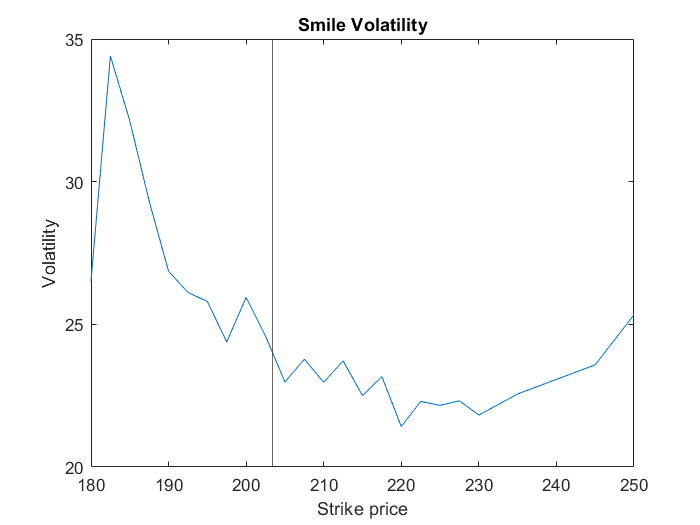

plot(Call.Strike, Call.IV);
xline(Call.StockAlTempoInizio(1));
title("Smile Volatility");
xlabel("Strike price");
ylabel("Volatility");

# **COX-ROSS AND RUBINSTEIN EUROPEA E AMERICANA**

resultMyMP = table();


TimeSpec = crrtimespec(Call.TempoInizio(1), Call.TempoFine(1), Call.Period(1));
RateSpec = intenvset('Rates', Call.Rendimento(1), 'StartDates','31-Aug-2018', 'EndDates', Call.TempoFine(1));
StockSpec = stockspec(Call.Volatilita(1), Call.StockAlTempoInizio(1));
CRRTree = crrtree(StockSpec,RateSpec,TimeSpec);
%treeviewer(CRRTree)


for p = 1:height(Call)
    c0=optstockbycrr(CRRTree,'Call',Call.Strike(p),Call.TempoInizio(p), Call.TempoFine(p));
    cEU = EuropeanCoxRossRubistein(Call.Period(p),Call.StockAlTempoInizio(p),Call.Strike(p),Call.Rendimento(p),Call.Volatilita(p),Call.DCF(p));
    cUS = AmericanCall(Call.StockAlTempoInizio(p),Call.Strike(p) ,Call.Rendimento(p) , Call.DCF(p) , Call.Volatilita(p) ,Call.Period(p) );
    resultMyMP.CEU(p) = cEU;
    resultMyMP.CUS(p) = cUS;
    resultMyMP.MatlabEuropeanCall(p) = c0;
    resultMyMP.CallValue(p) = Call.PrezzoCall(p);

end
disp(resultMyMP);

      CEU         CUS       MatlabEuropeanCall    CallValue
    ________    ________    __________________    _________

      23.966      24.183          23.737               25  
      21.649      21.845          21.404             22.7  
      19.333      19.508          19.071             20.3  
      17.016       17.17          16.738            18.35  
      14.998      15.134          14.718            16.15  
      13.297      13.417           13.03            14.15  
      11.596        11.7          11.342             13.8  
      9.8942      9.9838          9.6541            10.45  
       8.193      8.2671           7.966             8.85  
      6.4917      6.5505          6.2779              7.4  
      5.4018      5.4507          5.2081              6.1  
      4.6269      4.6688          4.4569             4.95  
      3.8519      3.886

# **PUT CALL PARITY**

C0=file(contains(file.Type,"Call"),:).Ask;
P0=file(contains(file.Type,"Put"),:).Ask;
MC0=mean(C0);
MP0=mean(P0);
Strike=mean(file.Strike);
putCallParity(MC0,Call.StockAlTempoInizio(1),Strike,Call.Rendimento(1),MP0);

Valore p0 stimato dalla put call parity
    3.2729

Valore p0 dal mercato
    3.9090



function TestSTazionarieta(LogRet)
    % Kwiatowski-Phillips-Schmidt-Shin (KPSS) Test
    % h=0: non è possibile rigettare l'ipotesi nulla (H0: i dati derivano da un processo stazionario o da processi stazionari con tendenza in media (trend))
    % h=1: è possibile rigettare l'ipotesi nulla in favore dell'ipotesi alternativa (H1: i dati derivano da un processo non stazionario)
    hKPSSTEST = kpsstest(LogRet);
    disp('KPSS Test');
    disp(hKPSSTEST);
    % Augmented Dickey_Fuller (ADF) Test
    % h=1: vuol dire che non è presente un trend quindi si può procedere con gli altri test
    % senza dover detrendizzare (ovvero rifare le differenze tre elementi successivi)
    % h=0: vuol dire che è presente un trend, è necessario effettuare le
    % differenze successive e verificare se c'è ancora un trend
    N = ceil((length(LogRet)-1)^(1/3));
    hTS = adftest(LogRet,'model','TS','lags',0:N); %Trend-stationary model
    hAR = adftest(LogRet,'model','AR','lags',0:N); %Autoregressive model 
    hARD = adftest(LogRet,'model','ARD','lags',0:N); %Autoregressive model with drift
   
    disp('ADF Test - Trend-stationary model');
    disp(hTS);
    disp('ADF Test - Autoregressive model');
    disp(hAR);
    disp('ADF Test - Autoregressive model with drift variant');
    disp(hARD);
    
end

function TestCorrelazione(LogRet)
    % autocorrelazione parziale e non
    N = ceil((length(LogRet)-1)^(1/3));
    figure;
    l=size(LogRet);
    autocorr(LogRet,'NumLags',20)
    figure;
    parcorr(LogRet)
    % Ljung-Box Q-test for residual autocorrelation
    % H0: The data are independently distributed
    % Ha: The data are not independently distributed; they exhibit serial correlation.
    LogRet0Mean= LogRet - mean(LogRet);
    h_LjungBox = lbqtest(LogRet0Mean,'lags',1:N);
    disp('Ljung-Box Q-test for residual autocorrelation');
    disp(h_LjungBox);

end

function TestNormalita(LogRet)
    figure;
    % istrogramma della serie
    histogram(LogRet)
    dim = [.14 .6 .3 .3];
    media = sprintf('%s = %f','media',mean(LogRet));
    mediana = sprintf('%s = %f','mediana',median(LogRet));
    deviazione = sprintf('%s = %f','std',std(LogRet));
    k = sprintf('%s = %f','kurtosis',kurtosis(LogRet));
    skew = sprintf('%s = %f','skewness',skewness(LogRet));
    str = {media,mediana,deviazione,k,skew}; 
    annotation('textbox',dim,'String',str,'FitBoxToText','on');
    
    
    % QQ-plot of the Log Returns
    pd = makedist('Normal');
    figure;
    % confronto tra il qqplot generato dalla serie e quello di unanormale standard
    qqplot(LogRet,pd);
    
    % Lilliefors (Kolmogorov-Smirnov) (Lillie) Test on the Log Returns
    % H0: i dati provengono da una popolazione distribuzione normale
    % H1: i dati provengono da una popolazione con distribuzione non normale e sconosciuta.
    % h=0: non è possibile rigettare l'ipotesi nulla, h=1: si può rigettare l'ipetesi nulla.
    hLilliefors = lillietest(LogRet);
    
    disp('Lilliefors Test');
    disp(hLilliefors);
    
    
    % Jarque-Bera Normality Test on the Log Returns
    % test di normalità, si basa sull'asimmetria e sulla curtosi della distribuzione
    % H0:  sia asimmetria che curtosi in eccesso siano nulle. (come nella distribuzione normale)
    % h=0: non è possibile rigettare l'ipotesi nulla, h=1: si può rigettare l'ipetesi nulla.
    hJarqueBera = jbtest(LogRet);
    
    disp('Jarque-Bera Test');
    disp(hJarqueBera);
    % Shapiro-Wilk Normality Test on the Log Returns
    % D'Agostino Pearson Normality Test on the Log Returns


end

function TestEteroschedasticita(Titolo)
    mdl = fitlm(Titolo.Datenum,Titolo.LogRet);
    plot(mdl);
end

function [up,dw,c] = BlackSholes(S0,k,rf,dfc,v_a)
    pt = 1/(v_a*sqrt(dfc));
    lg = log(S0/k);
    up =  pt *  ( lg +  ( rf +((v_a*v_a)/2) )*dfc  );
    dw =  pt *  ( lg +  ( rf -((v_a*v_a)/2) )*dfc  );
    c = S0*normcdf(up) -k * exp(-rf*dfc) *normcdf(dw);
end

 function  AmericanPut ( S0 ,X ,r_periodo , dcf , sigma ,M )
     % version : 14 Feb 2009
     % compute constants
     f7 = 1; 
     dt = dcf / M ; 
     
     u = exp ( sigma * sqrt ( dt )) ; 
     d = 1 / u;
     p = ( exp ( r_periodo/M  ) - d) / ( u - d );
     %sconto su C
     v = exp (- r_periodo/M  );

    
     % initialise asset prices at maturity ( period M)
     S = zeros ( M + 1 ,1) ;
     S ( f7 +0) = S0 * d ^ M;
     for j = 1: M
        S ( f7 + j ) = S( f7 + j - 1) * u / d ;
     end
    
     % initialise option values at maturity ( period M )
     P = max (X - S , 0) ;
    
     % step back through the tree
     for i = M -1: -1:0
        for j = 0: i
            P ( f7 +j ) = v * ( p * P( f7 + j + 1) + (1 - p) * P( f7 +j )) ;
            S ( f7 +j ) = S ( f7 + j) / d;
    
            P ( f7 +j ) = max (P( f7 + j ) ,X - S( f7 + j )) ;
         end
     end
     P0 = P( f7 +0) ;
     disp("Valore Put con modello Cox Ross e Rubinstein americano");
     disp(P0);
 end

function C0= AmericanCall ( S0 ,X ,r_periodo , dcf , sigma ,M )

    %m=period
    %divido il dcf in periodi
     f7 = 1; 
     dt = dcf / M ; 
     
     u = exp ( sigma * sqrt ( dt )) ; 
     d = 1 / u;
     p = ( exp ( r_periodo/M  ) - d) / ( u - d );
     %sconto su C
     v = exp (- r_periodo/M  );

    
     % inizializzo il prezzo alla maturita
     S = zeros ( M + 1 ,1) ;
     
     %ho inizializzato S1 con S0*d^Period  cosi basta decrementare d e
     %aumentare u per ottenre i prezzi dell'ultimo livello
     S( f7 +0) = S0 * d ^ M;
     for j = 1: M
        S( f7 + j ) = S( f7 + j - 1) * u / d ;
     end
    
     %inizializzo il valore dell opzione alla maturita
     %l'opzione avra lo stesso numero di elementi di S inizializzati al max
     C = max ( S - X , 0) ;
     % step back through the tree
     for i = M -1: -1:0
        for j = 0: i
            C ( f7 +j ) = v * ( p * C( f7 + j + 1) + (1 - p) * C( f7 +j )) ;
            
            S ( f7 +j ) = S(f7 + j) / d;
    
            C ( f7 +j ) = max ( C( f7 + j ) , S( f7 + j ) - X) ;
         end
     end
     C0 = C( f7 +0) ;
end

function call= EuropeanCoxRossRubistein(Period,S0,Strike,rf_anno,v_a,dcf)
    sum=0;
    u=exp(v_a*sqrt(dcf/Period));
    d=1/u;
    p=(rf_anno/Period+1-d)/(u-d);
    q=(u-(rf_anno/Period+1))/(u-d);
    for i=0:Period
        if (u^(Period-i)*d^(i)*S0)>Strike
            sum=sum+( (u^(Period-i)*d^i*S0-Strike) * p^(Period-i) * q^i * nchoosek(Period,i));   
        end
    end 
    call=(1/((1+rf_anno)^Period))*sum;
end

function putCallParity(C0,S0,k,r,p0Real)
    p0=k/(1+r)-S0+C0;
    disp("Valore p0 stimato dalla put call parity");
    disp(p0);
    disp("Valore p0 dal mercato");
    disp(p0Real);
end

function Call = LoadInTable(Titolo,CallFile, S0)
   
    %Strike=187.50;	
    %c0 = 19.20;
    t0 = datetime(2019,7,16);
    Tf = datetime(2019,8,31);
    %rf_anno =  0.02403;
    DCF = (1/360)*  ( 360* (Tf.Year -t0.Year) + 30 * (Tf.Month -t0.Month) + (Tf.Day-t0.Day) ) ;
    %rf periodale
    Call = table;
    for i=1:height(CallFile)
        Call.TempoInizio(i) = t0;
        Call.TempoFine(i) = Tf;
        Call.Period(i) = 4;
        Call.StockAlTempoInizio(i) = S0;
        Call.Strike(i) = CallFile.Strike(i);
        Call.Rendimento(i) =  0.02403*DCF;
        Call.DCF(i) = DCF;
        Call.Volatilita(i) = std(Titolo.LogRet)*sqrt(360);
        Call.PrezzoCall(i) = CallFile.Ask(i);
        Call.IV(i) = CallFile.IV(i);
    end
end

function aapCallPut = importfile(filename, dataLines)
%IMPORTFILE Import data from a text file
%  AAPCALLPUT = IMPORTFILE(FILENAME) reads data from text file FILENAME
%  for the default selection.  Returns the data as a table.
%
%  AAPCALLPUT = IMPORTFILE(FILE, DATALINES) reads data for the specified
%  row interval(s) of text file FILENAME. Specify DATALINES as a
%  positive scalar integer or a N-by-2 array of positive scalar integers
%  for dis-contiguous row intervals.
%
%  Example:
%  aapCallPut = importfile("C:\Users\Valentino\Documents\MATLAB\aapCallPut.csv", [2, 65]);
%
%  See also READTABLE.
%
% Auto-generated by MATLAB on 18-Jul-2019 13:11:12

%% Input handling

% If dataLines is not specified, define defaults
if nargin < 2
    dataLines = [2, Inf];
end

%% Setup the Import Options
opts = delimitedTextImportOptions("NumVariables", 15);

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Strike", "Var2", "Var3", "Var4", "Var5", "Ask", "Var7", "Var8", "IV", "Volume", "Var11", "Type", "Var13", "Var14", "Var15"];
opts.SelectedVariableNames = ["Strike", "Ask", "IV", "Volume", "Type"];
opts.VariableTypes = ["double", "string", "string", "string", "string", "double", "string", "string", "double", "double", "string", "string", "string", "string", "string"];
opts = setvaropts(opts, [2, 3, 4, 5, 7, 8, 11, 12, 13, 14, 15], "WhitespaceRule", "preserve");
opts = setvaropts(opts, 9, "TrimNonNumeric", true);
opts = setvaropts(opts, 9, "ThousandsSeparator", ",");
opts = setvaropts(opts, [2, 3, 4, 5, 7, 8, 11, 12, 13, 14, 15], "EmptyFieldRule", "auto");
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Setup rules for import
opts.ImportErrorRule = "omitrow";
opts.MissingRule = "omitrow";

% Import the data
aapCallPut = readtable(filename, opts);

end

function ATVI = importATVIfile(filename, startRow, endRow)
%IMPORTFILE Import numeric data from a text file as a matrix.
%   ATVI = IMPORTFILE(FILENAME) Reads data from text file FILENAME for the
%   default selection.
%
%   ATVI = IMPORTFILE(FILENAME, STARTROW, ENDROW) Reads data from rows
%   STARTROW through ENDROW of text file FILENAME.
%
% Example:
%   ATVI = importfile('ATVI.csv', 2, 252);
%
%    See also TEXTSCAN.

% Auto-generated by MATLAB on 2019/07/11 14:40:47

%% Initialize variables.
delimiter = ',';
if nargin<=2
    startRow = 2;
    endRow = inf;
end
formatSpec = '%{yyyy-MM-dd}D%*s%*s%*s%f%f%f%[^\n\r]';
fileID = fopen(filename,'r');
dataArray = textscan(fileID, formatSpec, endRow(1)-startRow(1)+1, 'Delimiter', delimiter, 'TextType', 'string', 'HeaderLines', startRow(1)-1, 'ReturnOnError', false, 'EndOfLine', '\r\n');
for block=2:length(startRow)
    frewind(fileID);
    dataArrayBlock = textscan(fileID, formatSpec, endRow(block)-startRow(block)+1, 'Delimiter', delimiter, 'TextType', 'string', 'HeaderLines', startRow(block)-1, 'ReturnOnError', false, 'EndOfLine', '\r\n');
    for col=1:length(dataArray)
        dataArray{col} = [dataArray{col};dataArrayBlock{col}];
    end
end
fclose(fileID);
ATVI = table;
ATVI.Date = dataArray{:, 1};
ATVI.Close = dataArray{:, 2};
ATVI.AdjClose = dataArray{:, 3};
ATVI.Volume = dataArray{:, 4};
end